# Shallow-curved shell structure with geometric nonlinearities

Finite element model used in the following reference:

Jain, S., & Tiso, P. (2018). Simulation-free hyper-reduction for geometrically nonlinear structural dynamics: a quadratic manifold lifting approach. *Journal of Computational and Nonlinear Dynamics*, *13*(7), 071003. [https://doi.org/10.1115/1.4040021](https://doi.org/10.1115/1.4040021)

Finite element code taken from the following package:

Jain, S., Marconi, J., Tiso P. (2020). YetAnotherFEcode (Version v1.1). Zenodo. [http://doi.org/10.5281/zenodo.4011282](http://doi.org/10.5281/zenodo.4011282)

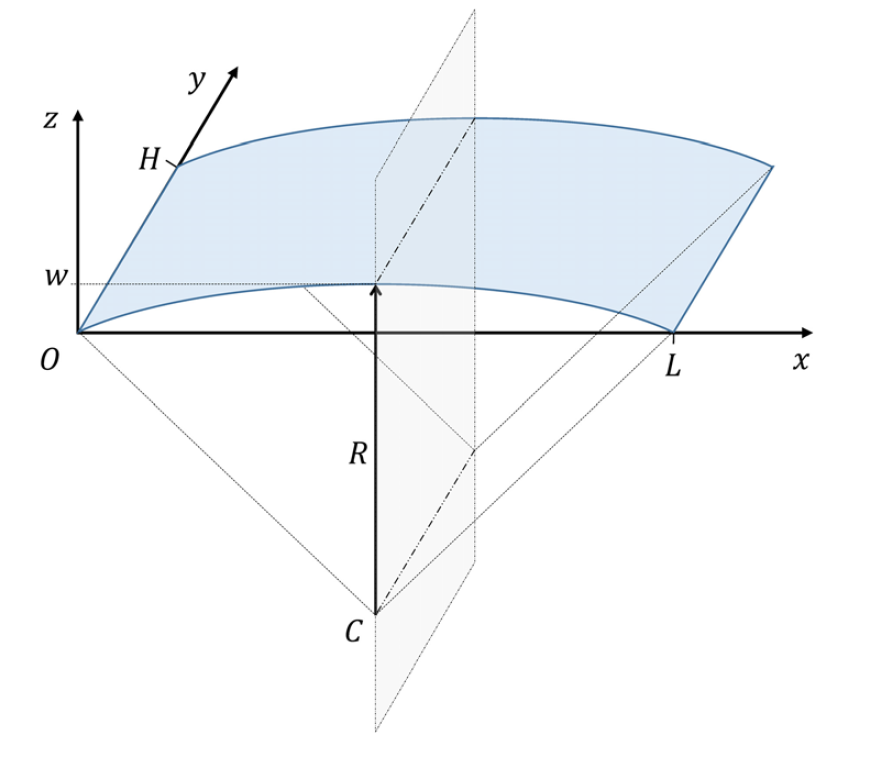

**system parameters**

nDiscretization = 30; % Discretization parameter (#DOFs is proportional to the square of this number)
epsilon = 0.003;

## generate model

Building FE model


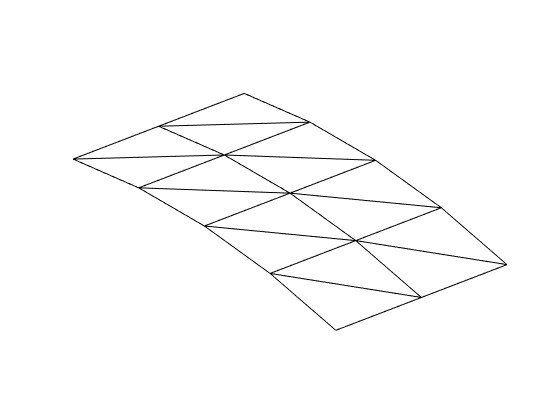

Assembling M,C,K matrices
Applying boundary conditions
Solving undamped eigenvalue problem


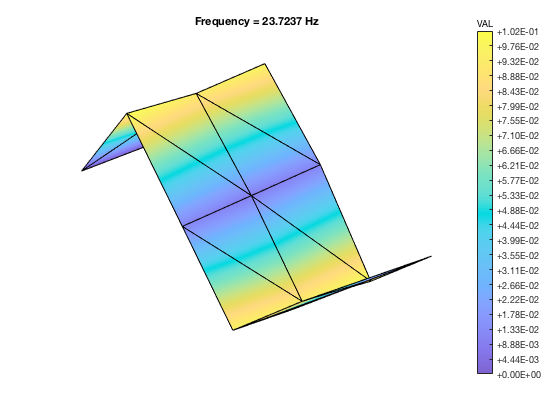

Using Rayleigh damping
Getting nonlinearity coefficients
Loaded tensors from storage
Assembling external force vector


[M,C,K,fnl,fext,outdof] = build_model(nDiscretization);

n = length(M); % number of degrees of freedom
disp(['Number of degrees of freedom = ' num2str(n)])

Number of degrees of freedom = 72


disp(['Phase space dimensionality = ' num2str(2*n)])

Phase space dimensionality = 144


[filterPSD] = build_stochasticF(outdof,n,epsilon);


## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

SS = StochasticSystem();   
set(SS,'filterPSD',filterPSD,'linear',false,'inputForcingType','vel')
set(SS,'M',M,'C',C,'K',K,'fnl',fnl);
set(SS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
set(SS.SSOptions,'ssMethod','indirect','tol',1e-12)
nRealization = 24;
T0 = 30; %% PSD frequency domain resolution is ~ 1/T0
nPoints = 2^17; %% control the accuracy of numerical differential equation

## Linear Modal analysis and full system simulation

method = "filter ImplicitMidPoint";
PSDpair = [out,out];

SS.add_random_forcing(nRealization, T0, nPoints,outdof);
freq_range = [30 55];

[V,D,W] = SS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.000000e-03
modal damping ratio for 2 mode is 2.000000e-03
modal damping ratio for 3 mode is 2.038945e-03
modal damping ratio for 4 mode is 2.059479e-03
modal damping ratio for 5 mode is 2.398277e-03



 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0030 + 1.4906i
  -0.0030 - 1.4906i
  -0.0068 + 3.3908i
  -0.0068 - 3.3908i
  -0.0072 + 3.5545i
  -0.0072 - 3.5545i
  -0.0075 + 3.6368i
  -0.0075 - 3.6368i
  -0.0115 + 4.8007i
  -0.0115 - 4.8007i



firts_res = abs(imag(D(1)));
tic
[w,outputPSD] = SS.monte_carlo_average(method,PSDpair,nRealization);
time_sde = toc;
disp(['Total number of ',num2str(nRealization),'# realization takes ',...
    num2str(time_sde),' amount of time'])

## linear analytic

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0030 + 1.4906i
  -0.0030 - 1.4906i

sigma_in = 3


*****************************************
Calculating FRC using SSM with master subspace: [1  2]
(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3
     2     0
     3     0
     0     2
     0     3
     3     0
     0     3

These are in resonance with the follwing eigenvalues of the slave subspace
   1.0e+02 *

  -0.0068 + 3.3908i
  -0.0068 + 3.3908i
  -0.0068 - 3.3908i
  -0.0068 - 3.3908i
  -0.0072 + 3.5545i
  -0.0072 + 3.5545i
  -0.0072 - 3.5545i
  -0.0072 - 3.5545i
  -0.0075 + 3.6368i
  -0.0075 + 3.6368i
  -0.0075 - 3.6368i
  -0.0075 - 3.6368i
  -0.0115 + 4.8007i
  -0.0115 - 4.8007i

sigma_out = 3
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     1     2

These are in resonance with the follwing eigenvalues of the master subspace
   1.0e+02 *

  -0.0030 + 1.4906i
  -0.0030 - 1.4906i

sigma_in =

Attempting manifold computation

 Run='freqSubint1.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.40e-02  2.11e+02    0.0    0.0    0.0
   1   1  1.00e+00  1.12e-01  1.83e-03  2.11e+02    0.0    0.0    0.0
   2   1  1.00e+00  1.12e-03  6.17e-07  2.11e+02    0.0    0.0    0.0
   3   1  1.00e+00  8.77e-08  1.09e-14  2.11e+02    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1          th1          eps
    0  00:00:00   2.1081e+02      1  EP      1.4906e+02   1.2611e-02   7.5155e-01   1.0000e-01
   10  00:00:01   2.0982e+02      2          1.4835e+02   1.7794e-02   1.7633e+00   1.0000e-01
   12  00:00:01   2.0981e+02      3  FP      1.4835e+02   1.7453e-02   1.8496e+00   1.0000e-01
   12  00:00:01   2.0981e+02      4  SN      1.4835e+02   1.7453e-02   1.8496e+00   1.0000e-01
   16

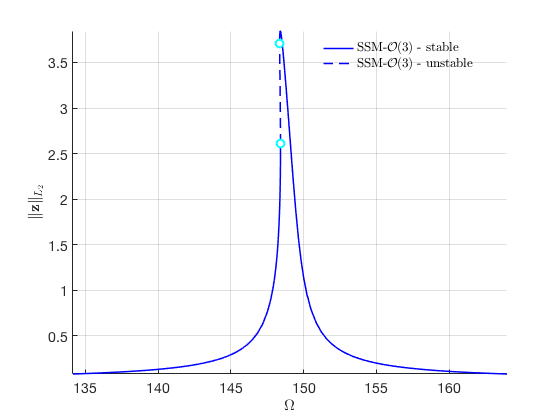

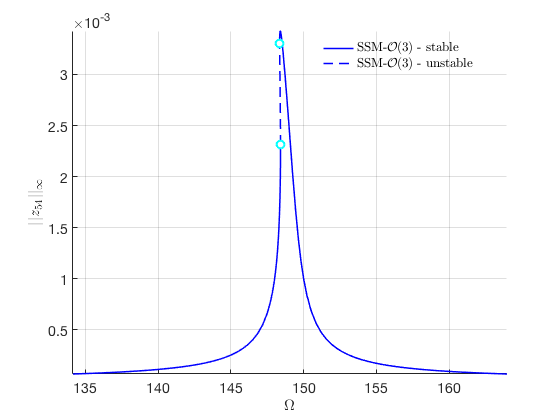

Total time spent on FRC computation = 00:00:10


[w_linear,linear_analytic] = SS.compute_linear_PSD(PSDpair,freq_range);

## SSM

% *Choose Master subspace (perform resonance analysis)*
S = SSM(SS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
set(S.PSDOptions, 'nPointfilter', 1)
masterModes = [1,2];
S.choose_E(masterModes);
order = 5; % Approximation order

tic
[wss,ssmPSD] = S.extract_PSD(PSDpair, order,'filter heun',freq_range);
time_ssm = toc;
disp([num2str(time_ssm),' amount of time'])

## Plot results

clear omega
clear Gxx
omega.w = w; Gxx.Gfull = outputPSD;%outputPSD;
omega.linear = w_linear; Gxx.linear_analytic = linear_analytic;
omega.wss = wss; Gxx.Gss = ssmPSD;
omega.w_full_linear = w_l; Gxx.full_linear = outputPSD_l;

plot_log_PSD(omega,Gxx,order,PSDpair,[20 50],true)
